maxEpochs = 10;
slice = 512;

rng(1)

ds = load('LabledData\raw_labled.mat', 'ls');
ds = ds.ls.Labels;
lables = ds.detect_blinks;
dir = ds.Properties.RowNames;

fs = 512;

downsampleRate = 4;
numClasses = 4;
frequencyLimits = [0.01 4000];


Ds = {};
for i = 1:numel(dir)    
    raw_data = csvread(dir{i},1,1);
    data = hl_filter(raw_data(:,1),true);%raw_data(:,1)is Fp1
    
%     %%%%%%%%% fft
%     stft(data,fs,'FrequencyRange','onesided')
%     t_data = stft(data,fs,'FrequencyRange','onesided');
%     t_data = t_data(size(t_data,1)-channel+1:size(t_data,1),:);
%     sample = floor(size(data,1)/size(t_data,2));
%     %%%%%%%%%fft

    r_data = [];
    lable = [];    
    masked = getmask({data,lables{i,1}});
%     %%%%%%fft
%     for j=1:size(t_data,2)
%         r_data = [r_data; data(1+(j-1)*sample)];
%         lable = [lable; masked{2}(1+(j-1)*sample)];
%     end
%     %%%%%%fft
    %%%%%%downsample
    d_data = downsample(data,downsampleRate);
    d_mask = downsample(masked{2},downsampleRate);
    Ds{i} = {d_data,d_mask};  
end


signalLength = 512;
chopedDs = {};

for i = 1:numel(Ds)
    firstNameLength = length(num2str(numel(Ds)));
    for j = 1:slice-1:numel(Ds{1,i}{1,1}(:,1))-slice-1
        secondNameLength = length(num2str(numel(Ds{1,i}{1,1}(:,1))-slice-1));
        signalLength = slice;
        data = Ds{1,i}{1,1}(j:j+slice-1,:);
        fb = cwtfilterbank('SignalLength',signalLength,'VoicesPerOctave', 48, ...
            'SamplingFrequency', fs/downsampleRate,'FrequencyLimits', [0.3333 4]);        
        [cfs, frq] = fb.wt(data);
        acfs = abs(cfs);
        acfs = acfs - min(min(acfs));
        th = quantile(acfs(:) , 0.975);
        acfs(acfs(:) > th) = th;
        acfs = acfs/th;
        t_data = im2uint8(acfs);
        firstName = num2str(i);
        secondName = num2str(j);
        while length(firstName)<firstNameLength
            firstName = ['0' firstName];
        end
        while length(secondName)<secondNameLength
            secondName = ['0' secondName];
        end
        imFileName = strcat(firstName,'_',secondName,'.jpg');
        imwrite(t_data,fullfile('WtImg',imFileName));
        chopedDs{end+1} = {t_data,Ds{1,i}{1,2}(j:j+slice-1)'};        
    end
end



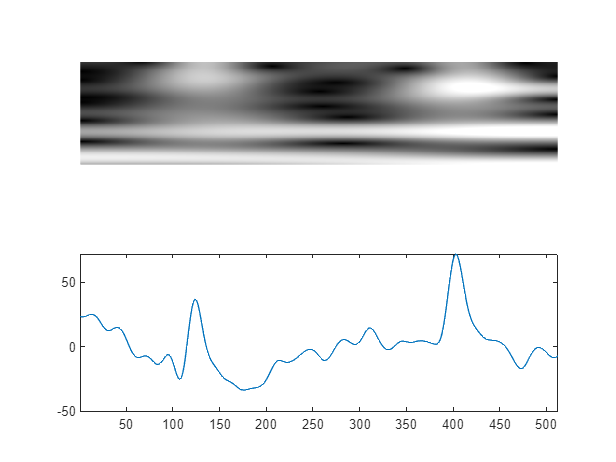

for i=14
    figure
    subplot(2,1,1)
    imshow(chopedDs{1, i}{1, 1}  )
    subplot(2,1,2)
    plot(Ds{1,1}{1,1}(1+(i-1)*slice:slice+(i-1)*slice,:))
    xlim([1 slice])
end

XTrain = {};
YTrain = {};
summarize = {};


for i = 1:numel(chopedDs)
    XTrain{end+1} = chopedDs{i}{1};
    YTrain{end+1} = chopedDs{i}{2};
    if sum(YTrain{end} == "blink") > 0
        summarize{end+1} = "blink";
    else
        summarize{end+1} = "n/a";
    end
end
allImgs = imageDatastore('WtImg\','FileExtensions','.jpg');
[trainIdx,~,testIdx] = dividerand(numel(XTrain),0.7,0,0.3);

XTest = XTrain(testIdx);
YTest = YTrain(testIdx);
XTrain = XTrain(trainIdx);
YTrain = YTrain(trainIdx);
STest = summarize(testIdx);
STrain = summarize(trainIdx);


imgTrain = allImgs.subset(trainIdx);
imgTest = allImgs.subset(testIdx);
i=1;
XT = cat(4,reshape(chopedDs{i}{1},[size(chopedDs{1}{1},1) size(chopedDs{1}{1},2) 1 1]), ...
    reshape(chopedDs{i+1}{1},[size(chopedDs{1}{1},1) size(chopedDs{1}{1},2) 1 1]));
YT = [];
Y = reshape(chopedDs{i}{2},[1 size(chopedDs{i}{1},2) 1 1]);
simpleY = reshape(chopedDs{i}{2},[size(chopedDs{i}{1},2) 1]);
for i = 1:numel(chopedDs)
    if i >=3
        XT = cat(4,XT,reshape(chopedDs{i}{1},[size(chopedDs{i}{1},1) size(chopedDs{i}{1},2) 1 1]));
    end
    
    YT = [YT; chopedDs{i}{2}];
    simpleY = [simpleY, reshape(chopedDs{i}{2},[size(chopedDs{i}{1},2) 1])];
end
Ylable = YT;
Ylable_vector = [];
for i = 1: size(Ylable,1)
    cate = 'n/a';
    if sum(Ylable(i,:)=='blink')>0
        cate = 'blink';
    elseif sum(Ylable(i,:)=='muscle-artifact')>0
        cate = 'muscle-artifact';
    end
    Ylable_vector = [Ylable_vector;categorical({cate})];
end




YT = sum(YT=='blink',2);
Yt=[];
for i = 1:numel(YT)
    if YT(i,1)>0
        Yt(end+1) = 1;
    else
        Yt(end+1) = 0;
    end
end

YNum = zeros([1 1 512 1457]);
YReg = zeros([1457 512]);
for i = 1:size(Y,4)
    
    a=(Y(:,:,:,i)=='blink')*1;
    YNum(:,:,:,i)= reshape(a,[1 1 512 1]);

    b=(Y(:,:,:,i)=='muscle-artifact')*(-1);
    YNum(:,:,:,i)= YNum(:,:,:,i) + reshape(b,[1 1 512 1]);
    YReg(i,:)= reshape(a+b,[1 512]);
end

cnn = simpleCNN(size(XT(:,:,1,1)),7,8,0.1);


slice = 512;
categories=3;
imSize=size(XT(:,:,1,1));
filterSize=5;
filterNum=16,;

filterNum = 16

dropoutLayerRegularization=0.1;

layers = [
    dropoutLayer(0.1)
fullyConnectedLayer(slice*categories,'Weights',rand(slice*categories,64),'Bias',rand(slice*categories,1),'Name','fc')
depthToSpace2dLayer([categories,slice],'Name','d2s')
transposeLayer()
softmaxLayer('Name','softMax')
regressionLayer('Name','reg')
];

assembledNet = assembleNetwork([cnnNet.Layers(1:13) ;
    layers])

Unable to resolve the name 'cnnNet.Layers'.

space = activation(assembledNet,XT(:,:,1,1),'d2s');
figure
for i =1:size(space,1)
    subplot(3,1,i)
    plot(space(i,:)')
    xlim([1 slice])
    title(['depthToSpace2dLayer' ' channel' num2str(i)])
end
softMax = activation(assembledNet,XT(:,:,1,1),'softMax');
figure
for i =1:size(softMax,3)
    subplot(size(softMax,3)+1,1,i)
    plot(softMax(:,:,i)')
    title(['softmaxLayer' ' channel' num2str(i)])
    xlim([1 slice])
end
subplot(size(softMax,3)+1,1,size(softMax,3)+1)
plot(sum(softMax,3))
title(['sum of '  num2str(i) ' channels'])
xlim([1 slice])
ylim([0.5 1.5])
reg = activation(assembledNet,XT(:,:,1,1),'reg');

% figure
% plot3(reshape(softMax(1,:,:),[512 1]),reshape(softMax(2,:,:),[512 1]),reshape(softMax(3,:,:),[512 1]),'.')



a=single(XT(:,:,:,:));
dlXT = dlarray(a,"SSCB");
softMaxOut = dlarray(reshape(single(XT(1:3,:,:,:)),[1 512 3 1457]),"UTCB");
extractX = extractdata(dlXT);

assembledNet = replaceLayer(assembledNet, 'imageinput', [sequenceInputLayer([110 1])]);

activation = activation(assembledNet,XT(:,:,1,1),1)

imSize=[ 110   512];
filterSizeC=7;
filterNum=8;
dropoutLayerRegularization=0.1;

filterSizeS = 5;
padingSize = floor(filterSizeS/2);
channels = 4;
slice = 1;

cnnLayers = [                
    sequenceInputLayer(imSize(1),"MinLength",512,'Name','sequenceInputLayer')
    %%%%%%%get S from T
    collectTLayer

    convolution2dLayer([filterSizeC filterSizeS], filterNum,'Padding',padingSize,'Name','cov1', ...
    'Weights',rand([7 5 1 8]),'Bias',rand([1 1 8]))
    batchNormalizationLayer('Offset',rand([1 1 8]),'Scale',rand([1 1 8]), ...
    'TrainedMean',rand([8 1]),'TrainedVariance',rand([8 1]))
    reluLayer()

    maxPooling2dLayer([4 1],'Stride',[4 1],'Name','pool1')

    convolution2dLayer([filterSizeC filterSizeS], filterNum*2,'Padding',padingSize,'Name','cov2', ...
    'Weights', rand([7 5 8 16]),'Bias',rand([1 1 16]))
    batchNormalizationLayer('Offset',rand([1 1 16]),'Scale',rand([1 1 16]), ...
    'TrainedMean',rand([16 1]),'TrainedVariance',rand([16 1]))
    reluLayer
    maxPooling2dLayer([4 1],'Stride',[4 1],'Name','pool2')
 
    convolution2dLayer([filterSizeC filterSizeS], filterNum*8,'Padding',padingSize,'Name','cov3', ...
    'Weights',rand([7 5 16 64]),'Bias',rand([1 1 64]))
    batchNormalizationLayer('Offset',rand([1 1 64]),'Scale',rand([1 1 64]), ...
    'TrainedMean',rand([64 1]),'TrainedVariance',rand([64 1]))
    maxPooling2dLayer([4 1],'Stride',[4 1],'Name','pool3')

    dropoutLayer(dropoutLayerRegularization,'Name','Dropout')
    dispatchSLayer
    fullyConnectedLayer(slice*channels,'Weights',rand(slice*channels,64),'Bias',rand(slice*channels,1),'Name','fc')

    softmaxLayer('Name','softMax')             
    classificationLayer('Name','classificationLayer')
    ];



cnnLayers = assembleNetwork([cnnLayers(1:end-1) 
    tcnNet.Layers(end) 
    ]);


activation = activations(cnnNet,imread(dataStoreCNN.UnderlyingDatastores{1, 1}.Files{1, 1}),'classoutput')

activation = 1×512×3 single array
activation(:,:,1) =

    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3335    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0

size(activation)

ans =      1   512     3


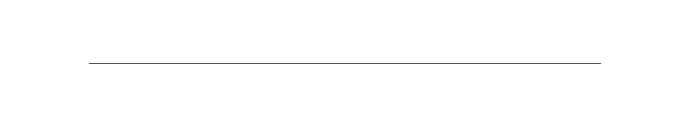

imshow(activation);